# Testing Neural Net

## Peceptron using moons.csv

Moons is perfect to test our perceptron as it has only 2 classes. We can easy represent this as a binary problem. Here we map the 2 classes in labels to equal 1 or -1. This is what happenes in the formatLabels method in the perceptron class.

rng(0)
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('moons.csv',3,0.6);

Sample of data:

ans = 10×3 cell array
    {'Feature 1'}    {'Feature 2'}    {'Label'  }
    {[   0.1567]}    {[   1.3182]}    {'Class A'}
    {[  -0.9705]}    {[   0.6211]}    {'Class A'}
    {[  -0.9086]}    {[   0.1598]}    {'Class A'}
    {[   0.7076]}    {[   0.2604]}    {'Class A'}
    {[  -1.2325]}    {[   0.9279]}    {'Class A'}
    {[  -0.6282]}    {[   0.8368]}    {'Class A'}
    {[   0.6124]}    {[   0.2656]}    {'Class A'}
    {[  -0.7009]}    {[  -0.0706]}    {'Class A'}
    {[   1.2655]}    {[   1.3637]}    {'Class A'}


test_examples size:	 60 2
test_labels size:	 60 1
train_examples size:	 90 2
train_labels size:	 90 1



train_labels;
train_values = grp2idx(train_labels);

% make labels binary 
train_values(train_values==2) = -1;


Now we can move onto training the model. Since there is only one output neuron, the array for weights must be the size of the input neurons. In this case it is 2. The size of the bias array is one, since there is only one output.


% default Learning rate is 0.1, default function is sigmoid.
m_p = my_fitcperc(train_examples, train_labels)

m_p =   my_ClassificationPerceptron with properties:

                  X: [90×2 double]
                  Y: [90×1 categorical]
            Weights: [-4.0761 2.2011]
               Bias: -1.9696
       LearningRate: 0.1000
         ClassNames: [2×1 categorical]
    NumObservations: []
           Function: 'Sigmoid'



% weights and bias of data
m_p.Weights

ans =    -4.0761    2.2011


m_p.Bias

ans = -1.9696

Now lets do some predictions!

p_p = m_p.predict(test_examples);
test_values = m_p.formatLabels(test_labels);

sum(test_values == p_p)/height(test_values)

ans = 0.7833

Finally we can see the abstraction. It will be linier as only one layer is present.

Where 1 is `ClassA` and -1 is `ClassB`.

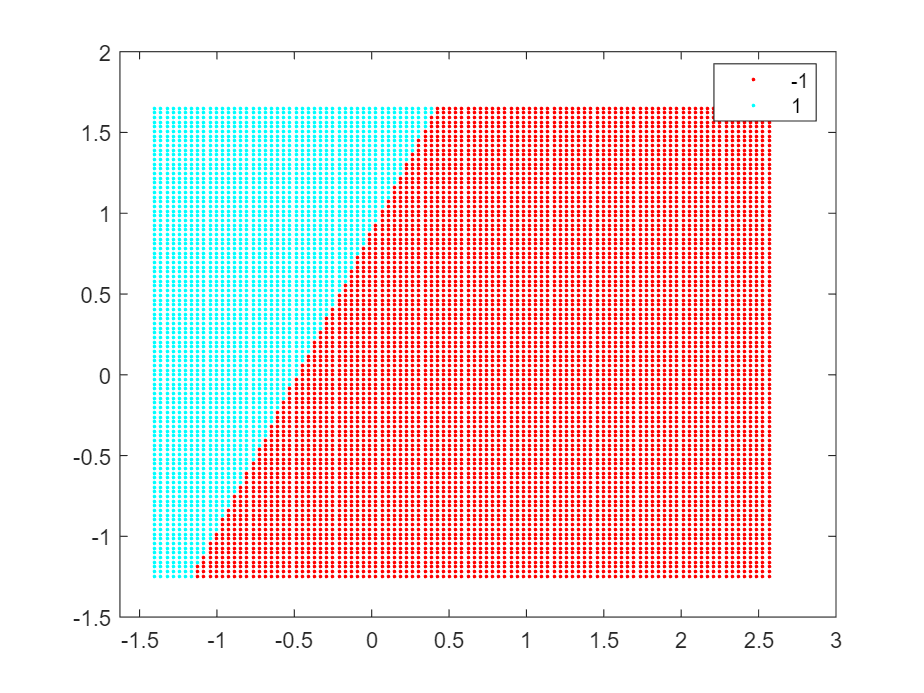

visualise_abstraction(m_p,'rc');

## Using Relu

I could not quite get this working in time, if you could tell me in the feedback where im going wrong here would be appreciated. Currently only generates output for one class! No good! Or maybe I am using the function incorrectly.


% with relu
m_p = my_fitcperc(train_examples, train_labels,'Function','Relu');

p_p = m_p.predict(test_examples);
test_values = m_p.formatLabels(test_labels);

sum(test_values == p_p)/height(test_values)

ans = 0.4333

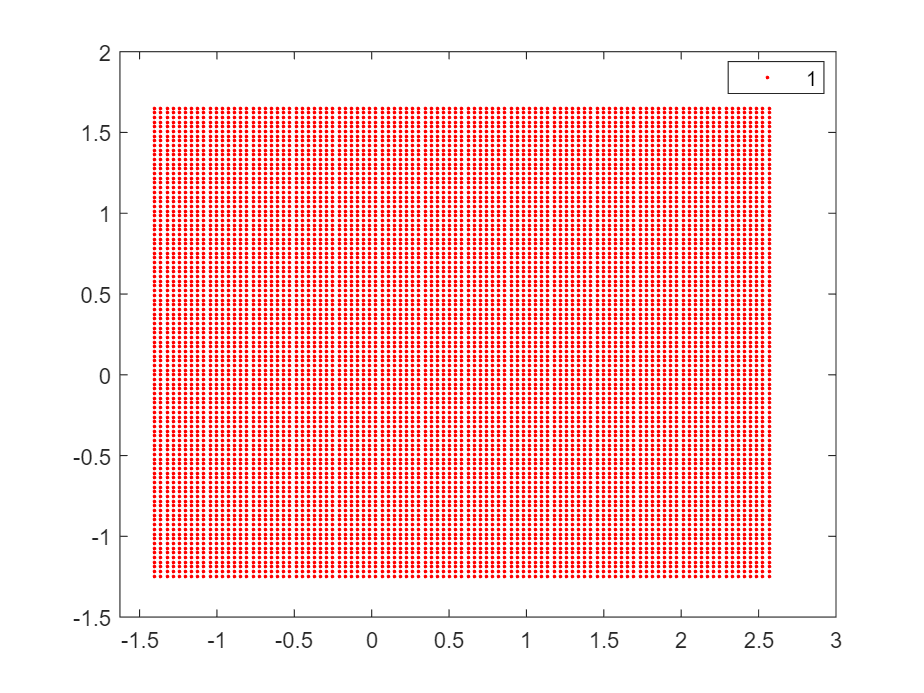


visualise_abstraction(m_p,'rc');